close("all"); clear; clc;

t = sym('t');
N = Frame;
O = Point;

names = {
    'psi';
    'theta';
    'phi'
    };

eul = dynamicVariables(names{:});
yaw = eul(1);
pitch = eul(2);
roll = eul(3);

Nyaw = N.orientNew('z',yaw);
Npitch = Nyaw.orientNew('y',pitch);
Nroll = Npitch.orientNew('x',roll);

names = {
    'x';
    'y';
    'z'
    };

[px,py,pz] = dynamicVariables(names{:});
Gb = O.locateNew([px,py,pz].');

caster = newParameters("varepsilon");
Nc = Nroll.orientNew('y',caster);
steer = dynamicVariable("delta");
Nsteer = Nc.orientNew('z',steer);

names = {
    'a';
    'e';
    'f';
    'h'
    };

[a,e,f,h] = newParameters(names{:});
A = Gb.locateNew(-h.*Nroll.z);
B = A.locateNew(a.*Nc.x);
Gf = B.locateNew(e.*Nsteer.x + f.*Nsteer.z);

T = Pose(Nsteer,Gf);
V = Twist(T).vector();

q_all = [
    yaw;
    pitch;
    roll;
    steer;
    px;
    py;
    pz;
    ];

q  = GeneralizedCoordinates(q_all,pz);

b = newParameters('b');
Cr = A.locateNew(-b.*Nroll.x);
TCr = Pose(Nyaw,Cr);
VCr = Twist(TCr).vector();
con = VCr(end);

C = ConstraintEquations(q,[],con);

names = {
    'omega_x';
    'omega_y';
    'omega_z';
    'v_x';
    'v_y';
    'v_z';
    'u'
    };

u_all = dynamicVariables(names{:}).';
u = GeneralizedCoordinates(u_all,u_all(end));

qd = diff(q.All,t);

kdes = [
    u.Independent - V;
    C.Velocity.MassMatrix*qd
    ];

[Mk,fk] = massMatrixForm(kdes,q.All);

qvars = prettify(q.All);
uvars = prettify(u.All);
params = [a,b,caster,e,f,h].';
vars = {qvars,uvars,params};

fM = matlabFunction(prettify(Mk),'Vars',vars);
ff = matlabFunction(prettify(fk),'Vars',vars);
clearvars -except fM ff;

root_str = "G:\My Drive\BikeSimResults";
dir_str = "\BigSports\ICRA25\Vx130Kph";
file_str = "\bikesim_results_130kph.csv";
T = readtable(root_str + dir_str + file_str);

params = [
    0.7525;
    0.6429;
    0.4189;
    0.0253;
    0.2344;
    0.5750
    ];

yaw = T.Yaw;
pitch = T.Pitch;
roll = T.Roll_E;
steer = T.Steer;
px = T.X_S2;
py = T.Y_S2;
pz = T.Z_S2;

q = [deg2rad([yaw,pitch,roll,steer]),px,py,pz].';

yaw_rate = T.AV_Y;
pitch_rate = T.AV_P;
roll_rate = T.AV_R;
steer_rate = -T.M_StrSys./0.2122;
px_rate = T.Vx_S2;
py_rate = T.Vy_S2;
pz_rate = T.Vz_S2;

qd = [yaw_rate,pitch_rate,roll_rate,steer_rate];
qd = [deg2rad(qd),[px_rate,py_rate,pz_rate]./3.6].';

wx = T.AVx;
wy = T.AVy;
wz = T.AVz;
vx = T.VxN_S1;
vy = T.VyN_S1;
vz = T.VzN_S1;

u = [deg2rad([wx,wy,wz]),[vx,vy,vz]./3.6,0.*vx].';

qd_est = zeros(size(qd));
u_est = zeros(size(u));

for k = 1:size(qd,2)
    M = fM(q(:,k),u(:,k),params);
    f = ff(q(:,k),u(:,k),params);
    qd_est(:,k) = M\f;
    u_est(:,k) = M*qd(:,k);
end

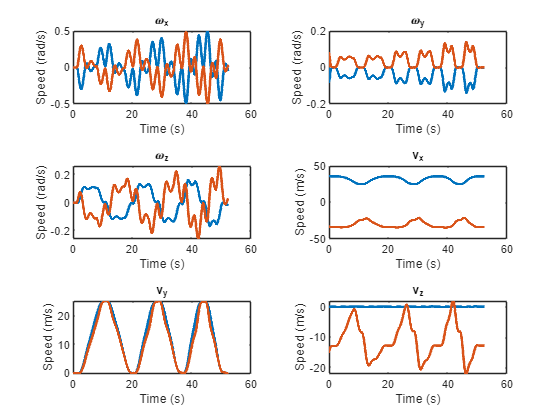

tiledlayout(3,2);

titles = [
    "\omega_x";
    "\omega_y";
    "\omega_z";
    "v_x";
    "v_y";
    "v_z"
    ];

units = [
    repmat("(rad/s)",[3,1]);
    repmat("(m/s)",[3,1]);
    ];

for k = 1:6
    nexttile;
    hold("on");
    plot(T.Time,u(k,:).',"LineWidth",2);
    plot(T.Time,u_est(k,:).',"LineWidth",2);
    hold("off");
    box("on");
    title(titles(k))
    xlabel("Time (s)");
    ylabel("Speed " + units(k));
end

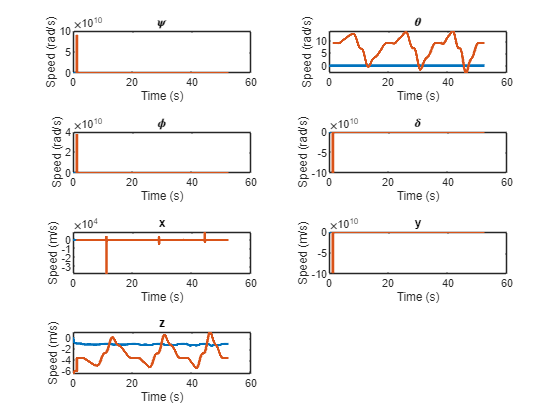

tiledlayout(4,2);

titles = [
    "\psi";
    "\theta";
    "\phi";
    "\delta";
    "x";
    "y";
    "z"
    ];

units = [
    repmat("(rad/s)",[4,1]);
    repmat("(m/s)",[3,1]);
    ];

for k = 1:7
    nexttile;
    hold("on");
    plot(T.Time,qd(k,:).',"LineWidth",2);
    plot(T.Time,qd_est(k,:).',"LineWidth",2);
    hold("off");
    box("on");
    title(titles(k),"Interpreter","tex")
    xlabel("Time (s)");
    ylabel("Speed " + units(k));
end